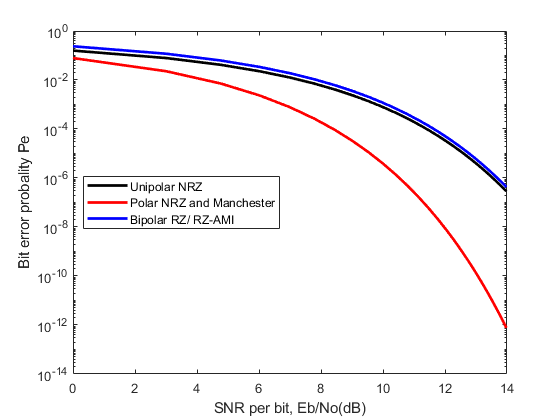

E=[0:1:25]; % Eb/N0=SNR of the recieved signal

%Unipolar NRZ
P1=(1/2)*erfc(sqrt(E/2));

%polar NRZ and Manchester code has same Pe for equiprobable 1's and 0's
P2=(1/2)*erfc(sqrt(E));

%Bipolar RZ/ RZ-AMI
P3=(3/4)*erfc(sqrt(E/2));

E=10*log10(E); % SNR in dB

semilogy(E,P1,'-k',E,P2,'-r',E,P3,'-b','LineWidth',2)
legend('Unipolar NRZ','Polar NRZ and Manchester','Bipolar RZ/ RZ-AMI','Location','best');
xlabel('SNR per bit, Eb/No(dB)');
ylabel('Bit error probality Pe');